# Pressure Solution

Problem Formulation


$$\begin{array}{l}
\Delta p=0\;\mathrm{for}\;0\le x\le L+2c,0\le y\le 2H\\
p\left(x,0\right)=p_T \left(x\right)\;\;\mathrm{for}\;0\le x\le L+2c\\
p\left(x,2H\right)=p_T \left(x\right)\;\mathrm{for}\;0\le x\le L+2c\\
p_x \left(0,y\right)=-G\;\mathrm{for}\;0\le y\le 2H\\
p_x \left(L+2c,y\right)=-G\;\mathrm{for}\;0\le y\le 2H
\end{array}$$


Transmural Pressure 


$$p_T(x) = \begin{cases} 
\gamma\sinh(\alpha(c-x_m))- G(x-c) & 0 \leq x \leq c\\ 
\gamma \sinh(\alpha(x-x_m)) & c<x<L+c\\
\gamma \sinh(\alpha((L+c)-x_m)) - G(x-(L+c)) & L+c \leq x \leq L+2c\\
\end{cases}
  $$


where $x_m =\frac{L+2c}{2},\gamma =-\frac{G}{\alpha \;\cosh \left(\alpha \;\frac{L}{2}\right)},\alpha^2 =\frac{3\mu \;}{H^3 }\mathrm{Da}$

The solution is


$$
  p(x,y) =   \sum\limits_{n = 1}^{\infty}\left( \frac{b_{2n-1}}{\mu_{2n-1}}\right)\frac{\cosh(\mu_{2n-1}(L+2c-x))-\cosh(\mu_{2n-1}x)}{\sinh((L+2c)\mu_{2n-1})}\sin(\mu_{2n-1}y) +  a_{2n-1} \frac{\sinh(\lambda_{2n-1}(2H-y))+\sinh(\lambda_{2n-1}y)}{\sinh(2H\lambda_{2n-1})}\cos(\lambda_{2n-1}x)
$$


where


$$
    \mu_{2n-1} = \frac{(2n-1)\pi}{2H},\\
    \lambda_{2n-1} = \frac{(2n-1)\pi}{L+2c},\\
    a_{2n-1}  = \frac{4}{L+2c} \left(\frac{G}{\lambda_{2n-1}^2} (1-\cos(\lambda_{2n-1} c))\right)- \frac{4}{L+2c}\left(\frac{\alpha\gamma}{\alpha^2 + \lambda_{2n-1}^2}\left(\cosh\left(\frac{\alpha L}{2}\right)\cos(\lambda_{2n-1} c) - \frac{\alpha}{\lambda_{2n-1}}\sinh\left(\frac{\alpha L}{2}\right)\sin(\lambda_{2n-1} c) \right)\right)\\
b_{2n-1} = \frac{4G}{(2n-1)\pi}
$$


In the script below, to avoid overflow errors, we use the following simplification


$$\frac{\sinh(\lambda(2H-y)) + \sinh(\lambda y)}{\sinh(2H\lambda)} =  \frac{ e^{-\lambda y} - e^{-\lambda(4H-y)} + e^{-\lambda (2H-y)} - e^{-\lambda(2H+y)}}{1-e^{-4H\lambda}}  \approx e^{-\lambda y} + e^{-\lambda(2H-y)$$


and similar for the term $\frac{\cosh \left(\mu \;\left(L+2c-x\right)\right)-\cosh \left(\mu \;x\right)}{\sinh \left(\left(L+2c\right)\mu \right)}$.

Note that $\mu$ is ininitally defined for viscosity and then reused for the eigenvalue $\mu_n$. We only use the viscosity to calculate $\alpha$, so this is notationally inconvenient, but does function correctly in the code.

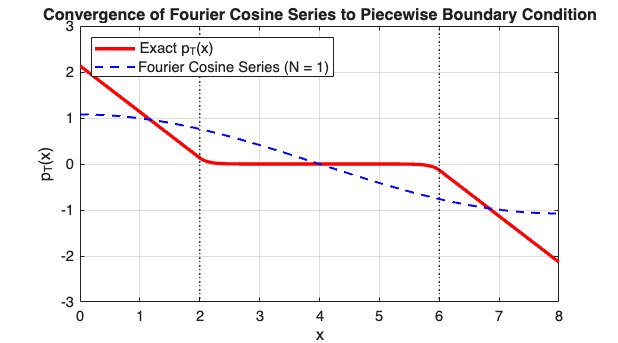

% Parameters
mu    = 1; % viscosity
Da    = 0.4; % Darcy coefficient
L     = 4; % Length of permeable region
c     = 2; % Length of extension region
G     = 1; % Pressure gradient
H     = 1; % Channel radius
alpha = 3*mu/(H^2*Da); % Related to permeability
gamma = -G/alpha * sech(alpha*L/2); % Constant from transmural pressure 
N_terms = 1; % Number of Fourier terms in the sum
Nx = 200; % Number of points in x direction
Ny = 200; % Number of points in y direction
W = L + 2*c; % Total domain width [0, W]
xm = W/2;

xpts = linspace(0,W,Nx);
ypts = linspace(0,2*H,Ny);
[X,Y] = meshgrid(xpts,ypts);

pT_exact = zeros(size(xpts));
for k = 1:length(xpts)
    x = xpts(k);
    if x>=0 && x<c
        pT_exact(k) = gamma * sinh(alpha*(c-xm)) - G*(x-c);
    elseif x>=c && x<= (L+c)
        pT_exact(k) = gamma * sinh(alpha*(x-xm));
    else
        pT_exact(k) = gamma * sinh(alpha*(L+c-xm)) - G*(x-(L+c));
    end
end

pT_fourier = zeros(size(xpts));
mG_fourier = zeros(size(ypts));
p_tb = zeros(size(X));
p_lr = zeros(size(X));
p_full = zeros(size(X));


for n = 1:N_terms
    lambda = (2*n-1) * pi / W; % eigenvalue for top/bottom
    % Calculate a sequence terms
    a1 = G/lambda^2 * (1-cos(lambda*c));
    a2 = -alpha * (gamma / (alpha^2 + lambda^2)) * cosh(alpha*L/2)*cos(lambda*c);
    a3 = -alpha^2 * (gamma / (lambda * (alpha^2 + lambda^2))) * sinh(alpha*L/2)*sin(lambda*c);
    a2nm1 = (4 / W )* (a1 + a2 + a3);

    % Calculate p_T usign Fourier cosine series
    pT_fourier = pT_fourier + a2nm1 * cos(lambda*xpts);

    mu = (2*n-1) * pi / (2*H); % eigenvalue for left/right
    % Calculate b sequence terms
    b2nm1 = 4*G/((2*n-1)*pi);

    % Calculate -G using Fourier sine series
    mG_fourier = mG_fourier - b2nm1 * sin(mu*ypts);

    % Calculate p_fourier(x,y)
    % Converted sinh and cosh terms to exponential expressions to avoid
    % overflow
    p_tb = a2nm1 * (exp(-lambda*(2*H - Y)) + exp(-lambda*Y)).* cos(lambda*X);
    p_lr = b2nm1 * ((exp(-mu*X) - exp(-mu*(W-X)))/mu) .* sin(mu*Y);
    p_full = p_full + p_tb + p_lr;
end

%% Plotting Transmural Pressure Fourier Series
% Comparing the plot of continuous extension of p_T(x) to the Fourier series

figure('Color', 'w', 'Position', [100, 100, 900, 500]);
plot(xpts, pT_exact, 'r-', 'LineWidth', 2.5, 'DisplayName', 'Exact p_T(x)');
hold on;
plot(xpts, pT_fourier, 'b--', 'LineWidth', 1.5, 'DisplayName', sprintf('Fourier Cosine Series (N = %d)', N_terms));
% Formatting
grid on;
xline(c, 'k:', 'LineWidth', 1.2, 'HandleVisibility', 'off');
xline(L+c, 'k:', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('x', 'FontSize', 12);
ylabel('p_T(x)', 'FontSize', 12);
title('Convergence of Fourier Cosine Series to Piecewise Boundary Condition', 'FontSize', 14);
legend('Location', 'northwest', 'FontSize', 11);
set(gca, 'FontSize', 11);

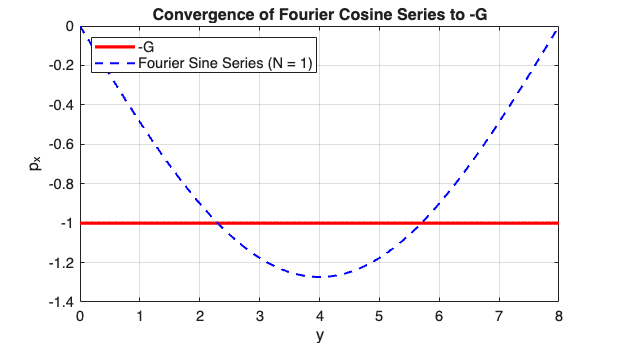

% Note the presence of Gibb's phenomenon here!
figure('Color', 'w', 'Position', [100, 100, 900, 500]);
plot(xpts, -G*ones(size(xpts)), 'r-', 'LineWidth', 2.5, 'DisplayName', '-G');
hold on;
plot(xpts, mG_fourier, 'b--', 'LineWidth', 1.5, 'DisplayName', sprintf('Fourier Sine Series (N = %d)', N_terms));

grid on;

xlabel('y', 'FontSize', 12);
ylabel('p_x', 'FontSize', 12);
title('Convergence of Fourier Cosine Series to -G', 'FontSize', 14);
legend('Location', 'northwest', 'FontSize', 11);
set(gca, 'FontSize', 11);

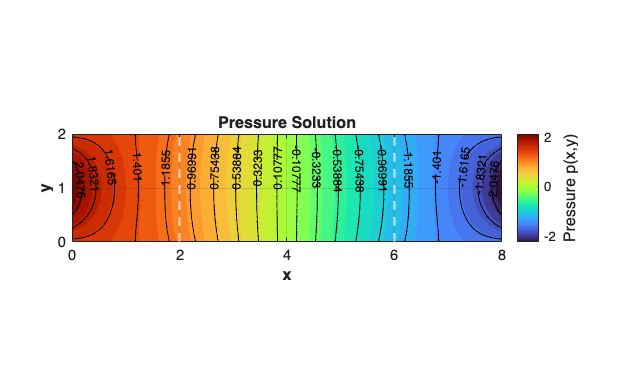

% Plotting the pressure in the channel
% Visualization: Level Curves (Contours) + Colorbar
figure('Color', 'w', 'Position', [100, 100, 950, 600]);

% Filled color contour plot background
[~, h_fill] = contourf(X, Y, p_full, 35, 'LineStyle', 'none');
hold on;

% Explicit level curves overlay with contour labels
[C, h_lines] = contour(X, Y, p_full, 20, 'k-', 'LineWidth', 0.8);
clabel(C, h_lines, 'FontSize', 9, 'Color', 'k', 'LabelSpacing', 200);

% Domain markers for Region boundaries
xline(c, 'w--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
xline(L+c, 'w--', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Formatting
colormap(turbo);           % Rich colormap for field intensity
cb = colorbar;
cb.Label.String = 'Pressure p(x,y)';
cb.Label.FontSize = 12;

xlabel('x', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('y', 'FontSize', 12, 'FontWeight', 'bold');
title('Pressure Solution', 'FontSize', 14);

axis equal tight;
set(gca, 'FontSize', 11, 'Layer', 'top');
grid on;